# RBE502 HW 10

We are desgining a controller for a 2DoF robot arm to sand a surface, as seen below:

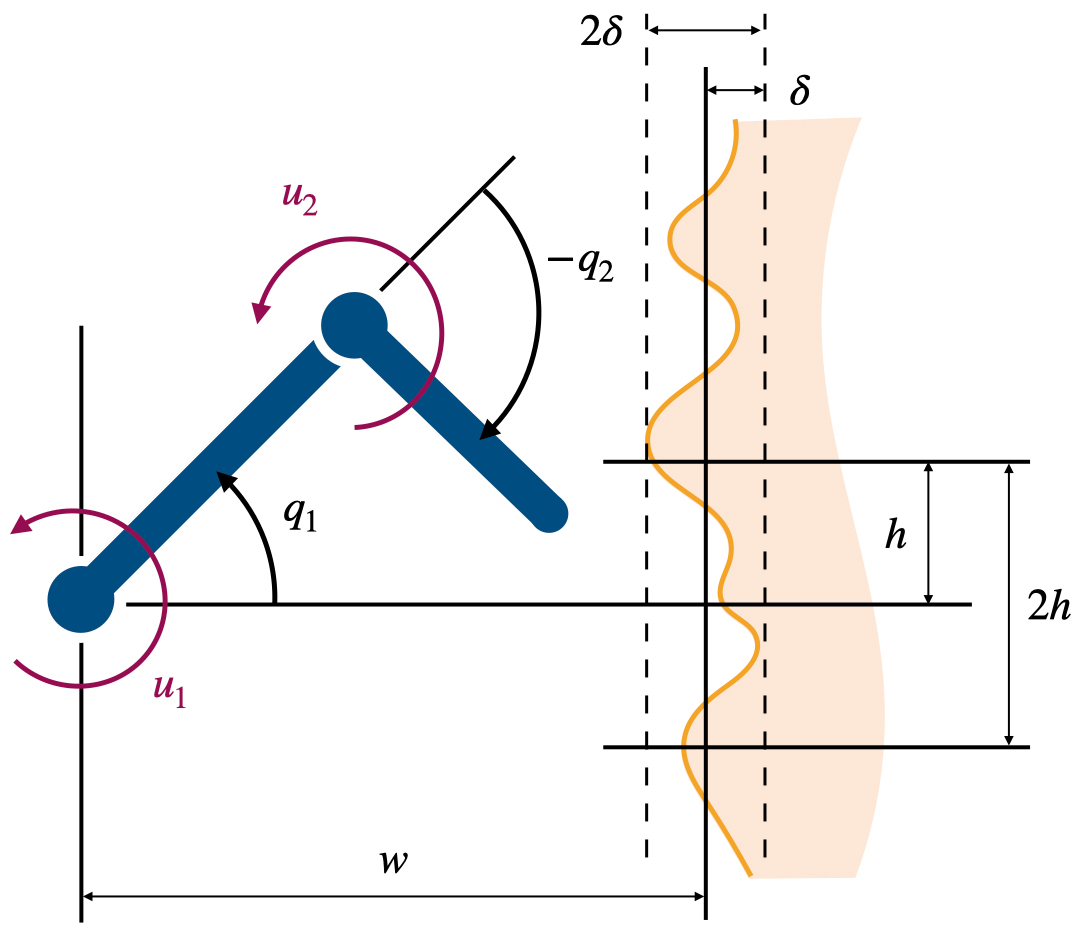

The distance between the robot arm is $w=\frac{l_1 +l_2 }{2}$. The section that needs to be sanded is $\left\lbrack -h,h\right\rbrack$ for $h=\frac{l_1 +l_2 }{3}$. The irregularities of the furface are measured at $\left\lbrack -\sigma ,\sigma \right\rbrack$ for $\sigma =\frac{l_1 +l_2 }{10}$. The horizontal force for sanding action is $5N\le r\le 7N$.

Design a control function for the sanding robot using feedback  linearization and impedance control. Use the same robot model as in  homework 7 and 8. That is: assume the center of mass of each link is  located at the end of the link and the mass moment of inertias are zero. Thus, we can model the system as a double pendulum:

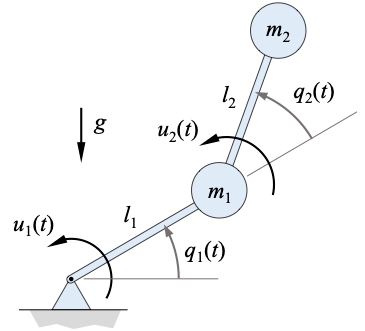

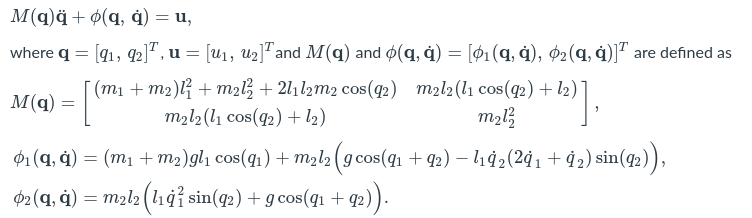

State:


$$x=\left\lbrack \begin{array}{c}
q_1 \\
q_2 \\
\dot{q_1 } \\
\dot{q_2 } 
\end{array}\right\rbrack$$


m1 = 2;
m2 = 1;
l1 = 1;
l2 = 1;
g = 9.81;

M = @(x) [ (m1+m2)*l1^2+m2*l2^2+2*l1*l2*m2*cos(x(2))      m2*l2*(l1*cos(x(2))+l2);
           m2*l2*(l1*cos(x(2))+l2)                        m2*l2^2                ];
phi = @(x) [ (m1+m2)*g*l1*cos(x(1))+m2*l2*(g*cos(x(1)+x(2))-l1*x(4)*(2*x(3)+x(4))*sin(x(2)));
             m2*l2*(l1*x(3)^2*sin(x(2))+g*cos(x(1)+x(2)));  ];

L  = @(x) [l2*cos(x(1) + x(2)) + l1*cos(x(1));
          l2*sin(x(1) + x(2)) + l1*sin(x(1))];

J = @(x) [ - l2*sin(x(1) + x(2)) - l1*sin(x(1)), -l2*sin(x(1) + x(2));
             l2*cos(x(1) + x(2)) + l1*cos(x(1)),  l2*cos(x(1) + x(2))];

Jdot = @(x) [ - x(3)*(l2*cos(x(1) + x(2)) + l1*cos(x(1))) - x(4)*l2*cos(x(1) + x(2)), -l2*cos(x(1) + x(2))*(x(3) + x(4));
            - x(3)*(l2*sin(x(1) + x(2)) + l1*sin(x(1))) - x(4)*l2*sin(x(1) + x(2)), -l2*sin(x(1) + x(2))*(x(3) + x(4))];
     

f = @(x) [x(3:4); -M(x)\phi(x)];
g = @(x) [0 0; 0 0; inv(M(x))];

Me = [m1 0; 0 m2;];
Be = [1 0; 0 0;];
syms k1 k2
K = [k1 0; 0 k2;];

d2q_d = @(x,r,z0) (Me*J(x))\(r - B*J(x)*x(3:4) - K*(L(x) - z0)) - J(x)\dJ(x)*x(3:4);



